Reading data and renaming variables

clearvars;

T = readtable('Project_Forecasting.xlsx');
T.Properties.VariableNames{1,1} = 'Date';
T.Properties.VariableNames{1,2} = 'Inf';

Splitting and plotting data with 80/20 ratio

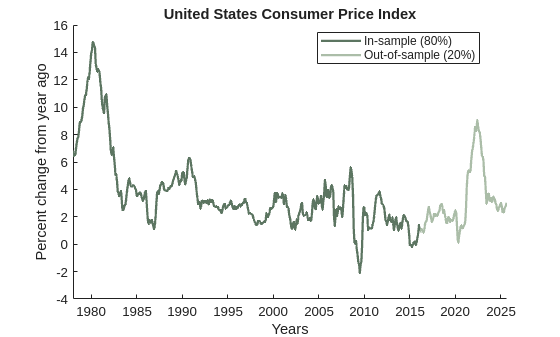

% Length and split index
N = height(T);
splitIdx = floor(0.8 * N);

% In-sample data
T_in = T(1:splitIdx, :);

% Out-of-sample data
T_out = T(splitIdx+1:end, :);

% Colors (sage palette)
darkSage = [0.36, 0.46, 0.38];
sage = [0.67, 0.74, 0.66];
purple = [0.612, 0.522, 0.753]; 
blue = [0.502, 0.620, 0.761]; 
pink = [0.816, 0.573, 0.655]; 

% Plot
figure;
hold on;

% In-sample: dark sage green
plot(T_in.Date, T_in.Inf, 'Color', darkSage, 'LineWidth', 1.7);

% Out-of-sample: sage green
plot(T_out.Date, T_out.Inf, 'Color', sage, 'LineWidth', 1.7);

% Titles & labels
title('United States Consumer Price Index');
xlabel('Years');
ylabel('Percent change from year ago');

% Legend
legend({'In-sample (80%)', 'Out-of-sample (20%)'}, 'Location', 'best');

hold off;

Checking for unit root

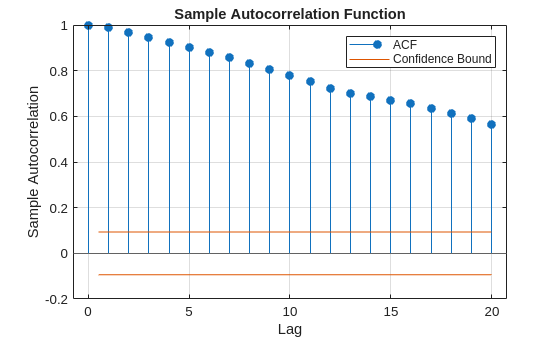

autocorr(T_in.Inf);


maxlags=12; % Monthly data, so minimum 12 lags
[h,pValue,stat,cValue,reg]=adftest(T_in.Inf,Model="ARD",Lags=0:maxlags);

% Using BIC information criterion to choose lags
BICall=zeros(maxlags+1,1);
for lag = 0:maxlags
    BICall(lag+1) = reg(lag+1).BIC; % Storing BIC values for each lag
end
[C,l]=min(BICall);


disp('Model: Case 2 (intercept, no trend)');

Model: Case 2 (intercept, no trend)


disp("BIC selected lag "+(l-1));

BIC selected lag 12


disp("p-value: "+pValue(l));

p-value: 0.3977


disp("Test statistic: "+stat(l));

Test statistic: -1.772


disp("5% C value: "+cValue(l));

5% C value: -2.8688


Changing data info first diference

T_in.Delta_Inf = [NaN; T_in.Inf(2:end)-T_in.Inf(1:end-1)];


% Checking (just to be sure) if the original data was I(1) or I(2)
maxlags=11;

maxlags = 11

[h2,pValue2,stat2,cValue2,reg2]=adftest(T_in.Delta_Inf,Model="ARD",Lags=0:maxlags);

BICall2=zeros(maxlags+1,1);
for lag = 0:maxlags
    BICall2(lag+1) = reg2(lag+1).BIC; % Storing BIC values for each lag
end
[C2,l2]=min(BICall2);


disp('Model: Case 2 (intercept, no trend)');

Model: Case 2 (intercept, no trend)


disp("BIC selected lag "+(l2-1));

BIC selected lag 11


disp("p-value: "+pValue2(l2));

p-value: 0.001


disp("Test statistic: "+stat2(l2));

Test statistic: -9.9235


disp("5% C value: "+cValue2(l2));

5% C value: -2.8688



% Our series, Delta_Inf is now stationary and no longer has a unit root.

Plots for the first difference

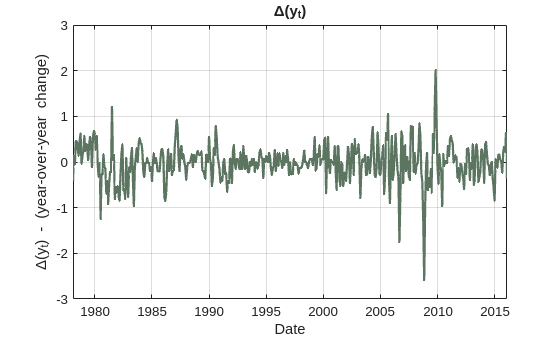

% Plot first difference (ΔInf) for in-sample
figure;
plot(T_in.Date(2:end), T_in.Delta_Inf(2:end), ...
    'Color', darkSage, 'LineWidth', 1.7);

title('\Delta(y_t)');
xlabel('Date');
ylabel('Δ(y_t) - (year-over-year change)');

grid on; 

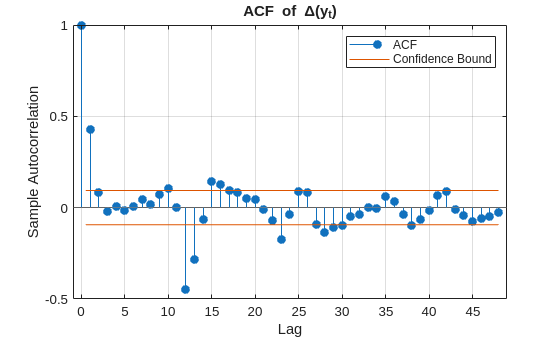


numLags = 48;

% --- ACF ---
autocorr(T_in.Delta_Inf, 'NumLags', numLags);
title('ACF of \Delta(y_t)');

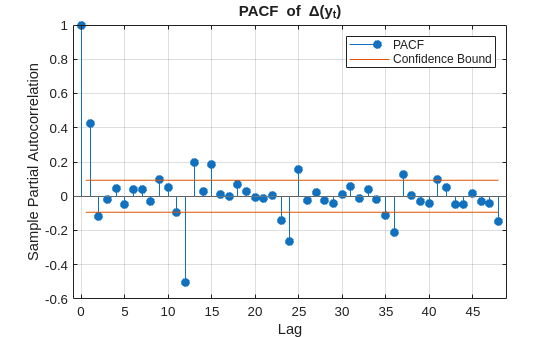


% --- PACF ---
parcorr(T_in.Delta_Inf, 'NumLags', numLags);
title('PACF of \Delta(y_t)');

Choosing number of lags for ARMA model using BIC 

-> result: `SARIMA(1,0,2)(2,0,1)_12`

pMax = 3;    % max non-seasonal AR
qMax = 3;    % max non-seasonal MA
PMax = 2;    % max seasonal AR
QMax = 2;    % max seasonal MA
d = 0;       % from your ADF result (you found Delta_Inf stationary => model on Delta or on level)
D = 0;       % seasonal difference (set to 0 or 1 depending on D you'll use)
s = 12;      % seasonal period (monthly)

Y = T_in.Delta_Inf;        
nObs = numel(Y);

% Preallocate results table
results = table();
row = 0;

% Helper to build lag vectors or empty if p==0
lagsVec = @(k) (k>0)*(1:k);

% Loop over candidate orders
for p = 0:pMax
    for q = 0:qMax
        for P = 0:PMax
            for Q = 0:QMax
                % Build ARIMA model object with requested lags
                if p>0
                    ARLags = 1:p;
                else
                    ARLags = [];
                end
                if q>0
                    MALags = 1:q;
                else
                    MALags = [];
                end
                if P>0
                    SARLags = s*(1:P);
                else
                    SARLags = [];
                end
                if Q>0
                    SMALags = s*(1:Q);
                else
                    SMALags = [];
                end

                % Create model object: keep Constant as NaN to let estimate decide
                Mdl = arima('ARLags',ARLags, 'MALags',MALags, ...
                            'D', d, 'Seasonality', s, ...
                            'SARLags',SARLags, 'SMALags',SMALags, ...
                            'Constant', NaN);

                % Try to estimate; skip models that fail
                try
                    [EstMdl,EstParamCov,logL,info] = estimate(Mdl, Y, 'Display','off');
                end

                % Count number of estimated parameters (k) robustly
                k = p+q+P+Q+1;
                % AR coefficients (after estimation EstMdl.AR is numeric array or empty)


                % Compute BIC using aicbic helper
                % aicbic expects logL, k, n
                [aicVal, bicVal] = aicbic(logL, k, nObs);

                % Save results
                row = row + 1;
                results(row,:) = {p,d,q,P,D,Q,logL,k,bicVal,aicVal,''};
            end
        end
    end
end

% Label the table and sort by BIC
results.Properties.VariableNames = {'p','d','q','P','D','Q','LogLikelihood','NumParams','BIC','AIC','FailMessage'};
resultsSorted = sortrows(results, 'BIC', 'ascend');

% Display top candidates
disp('Top 10 candidate models by BIC:');

Top 10 candidate models by BIC:


disp(resultsSorted(1:min(10,height(resultsSorted)),:));

    p    d    q    P    D    Q    LogLikelihood    NumParams     BIC       AIC      FailMessage
    _    _    _    _    _    _    _____________    _________    ______    ______    ___________

    1    0    2    2    0    1       -110.13           7        263.15    234.26    {0×0 char} 
    2    0    3    2    0    1       -106.43           9           268    230.86    {0×0 char} 
    2    0    2    2    0    1       -109.82           8        268.66    235.65    {0×0 char} 
    1    0    2    2    0    2       -109.92           8        268.86    235.85    {0×0 char} 
    1    0    3    2    0    1       -110.06           8        269.14    236.12    {0×0 char} 
    3    0    2    2    0    1       -107.85           9        270.84     233.7    {0×0 char} 
    2    0    3    2    0    2       -105.67          10         272.6    231.33    {0×0 char} 
    2    0    2    2    0    2       -109.31           9        273.77    236.63    {0×0 char} 
    3    0    3    2    0    1       -1


% Show best
best = resultsSorted(1,:);
fprintf('\nBest by BIC: SARIMA(%d,%d,%d)(%d,%d,%d)_%d with BIC = %.3f\n', ...
        best.p, best.d, best.q, best.P, best.D, best.Q, s, best.BIC);


Best by BIC: SARIMA(1,0,2)(2,0,1)_12 with BIC = 263.150


Now doing the same but using AIC 

-> result: `SARIMA(2,0,3)(2,0,1)_12 (SAME ONE)`

%now AIC
resultsSorted = sortrows(results, 'AIC', 'ascend');

% Display top candidates
disp('Top 10 candidate models by AIC:');

Top 10 candidate models by AIC:


disp(resultsSorted(1:min(10,height(resultsSorted)),:));

    p    d    q    P    D    Q    LogLikelihood    NumParams     BIC       AIC      FailMessage
    _    _    _    _    _    _    _____________    _________    ______    ______    ___________

    2    0    3    2    0    1       -106.43           9           268    230.86    {0×0 char} 
    2    0    3    2    0    2       -105.67          10         272.6    231.33    {0×0 char} 
    3    0    3    2    0    1       -106.39          10        274.05    232.78    {0×0 char} 
    3    0    3    2    0    2       -105.64          11        278.67    233.28    {0×0 char} 
    3    0    2    2    0    1       -107.85           9        270.84     233.7    {0×0 char} 
    1    0    2    2    0    1       -110.13           7        263.15    234.26    {0×0 char} 
    3    0    2    2    0    2       -107.21          10        275.68    234.41    {0×0 char} 
    2    0    2    2    0    1       -109.82           8        268.66    235.65    {0×0 char} 
    1    0    2    2    0    2       -1


% Show best
best = resultsSorted(1,:);
fprintf('\nBest by AIC: SARIMA(%d,%d,%d)(%d,%d,%d)_%d with AIC = %.3f\n', ...
        best.p, best.d, best.q, best.P, best.D, best.Q, s, best.AIC);


Best by AIC: SARIMA(2,0,3)(2,0,1)_12 with AIC = 230.862


FORECASTING

% Initialization
y = T.Inf;
n = length(y);
h = ceil(0.2*n);
train = 1:n-h;
test = n-h+1:n;
fore = NaN(h,4); % 3 different forecasts


% Always the same length of the training set
window_size = length(train); 


% 1. ROLLING WINDOW LOOP
for j = 1:h
    
    % Defining the rolling window
    idx_start = j;
    idx_end = window_size + j - 1;
    current_train_data = y(idx_start : idx_end);
    
    % Index of the forecasted value in y - the whole set
    idx_forecast = idx_end + 1; 


    %% FORECAST 1: SARIMA(1,1,2)(2,0,1)_12 - given by BIC
    
    % Definition of the model
    Mdl1 = arima('ARLags', 1, 'D', 1, 'MALags', 1:2, 'Seasonality', 12, ...
                'SARLags', 12*(1:2), 'SMALags', 12);
    
    % Estimating the model on a current training window
    estMdl1 = estimate(Mdl1, current_train_data, 'Display', 'off');
    
    % One step-ahead forecast
    fore(j, 1) = forecast(estMdl1, 1, 'Y0', current_train_data);
    
    %% FORECAST 2: SARIMA(2,1,3)(2,0,1)_12 - given by AIC

    % Definition of the model
    Mdl2 = arima('ARLags', 1:2, 'D', 1, 'MALags', 1:3, 'Seasonality', 12, ...
                'SARLags', 12*(1:2), 'SMALags', 12);
    
    % Estimating the model on a current training window
    estMdl2 = estimate(Mdl2, current_train_data, 'Display', 'off');
    
    % One step-ahead forecast
    fore(j, 2) = forecast(estMdl2, 1, 'Y0', current_train_data);
    
    %% FORECAST 3: SEASONAL RANDOM WALK -> but it is terrible
    
    % The forecast is just the value 12 lags before
    idx_prev_season = idx_forecast - 12; 
    fore(j, 3) = y(idx_prev_season);


    %% FORECAST 4: RANDOM WALK
    
    % The forecast is just the value 1 lag before
    idx_prev_value = idx_forecast - 1; 
    fore(j, 4) = y(idx_prev_value);
    
end


% 2. RMSFE
actual = y(test);
rmse_sarima1 = sqrt(mean((actual - fore(:,1)).^2));
rmse_sarima2 = sqrt(mean((actual - fore(:,2)).^2));
rmse_srw = sqrt(mean((actual - fore(:,3)).^2));
rmse_rw = sqrt(mean((actual - fore(:,4)).^2));
disp(['RMSFE SARIMA (using BIC): ', num2str(rmse_sarima1)]);

RMSFE SARIMA (using BIC): 0.30827


disp(['RMSFE SARIMA (using AIC): ', num2str(rmse_sarima2)]);

RMSFE SARIMA (using AIC): 0.30635


disp(['RMSFE SRW: ', num2str(rmse_srw)]);

RMSFE SRW: 2.4123


disp(['RMSFE RW: ', num2str(rmse_rw)]);

RMSFE RW: 0.39368


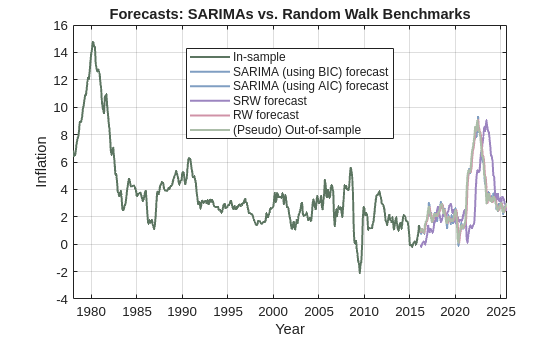



% 3. Plots with the forecasted and actual values
figure;
plot(T.Date, y, 'Color', darkSage, 'LineWidth', 1.5, 'DisplayName', 'In-sample');
hold on;
plot(T.Date(test), fore(:, 1), 'Color', blue, 'LineWidth', 1.5, 'DisplayName', 'SARIMA (using BIC) forecast');
plot(T.Date(test), fore(:, 2), 'Color', blue, 'LineWidth', 1.5, 'DisplayName', 'SARIMA (using AIC) forecast');
plot(T.Date(test), fore(:, 3), 'Color', purple, 'LineWidth', 1.5, 'DisplayName', 'SRW forecast');
plot(T.Date(test), fore(:, 4), 'Color', pink, 'LineWidth', 1.5, 'DisplayName', 'RW forecast'); 
plot(T.Date(test), y(test), 'Color', sage, 'LineWidth', 1.5, 'DisplayName', '(Pseudo) Out-of-sample');
hold off;
legend('show', 'Location', 'best');
title('Forecasts: SARIMAs vs. Random Walk Benchmarks');
xlabel('Year'); 
ylabel('Inflation');
grid on;

TESTING MODEL ACCURACY

% We first define vectors of error estimates
err_sarima1 = actual - fore(:,1);
err_sarima2 = actual - fore(:,2);
err_srw = actual - fore(:,3);
err_rw = actual - fore(:,4);

% We obviously beat the SRW, so we will compare with the more precise
% Random Walk

% To compare forecasts, we can use Diebold and Mariano test - if the two
% forecasts are identical, their error estimates should all be normally
% distributed and their covariance should be zero. We can check for that!

function [DMstat, pValue] = dmtest(e1, e2, h)

    % e1 and e2 = forecast errors (not losses)
    d = e1.^2 - e2.^2;     % loss differential
    T = length(d);
    mean_d = mean(d);

    % Newey-West estimator for variance (lag = h-1)
    gamma0 = var(d,1);

    gamma = zeros(h-1,1);
    for lag = 1:h-1
        gamma(lag) = (1/T) * sum((d(1:end-lag) - mean_d) .* (d(lag+1:end) - mean_d));
    end

    var_d = gamma0 + 2 * sum(gamma);

    DMstat = mean_d / sqrt(var_d/T);

    % Two-sided p-value from normal distribution
    pValue = 2 * (1 - normcdf(abs(DMstat)));
end

[DMstat1, pValue_DM1] = dmtest(err_sarima1, err_rw, 1);
[DMstat2, pValue_DM2] = dmtest(err_sarima2, err_rw, 1);
[DMstat3, pValue_DM3] = dmtest(err_sarima1, err_sarima2, 1); %Additionaly, we can check if the forecasts using number of parameters from AIC or BIC are different

disp(['p-value of DM test of SARIMA(1,1,2)(2,0,1) vs RW: ', num2str(pValue_DM1)]);

p-value of DM test of SARIMA(1,1,2)(2,0,1) vs RW: 0.022889


disp(['p-value of DM test of SARIMA(2,1,3)(2,0,3) vs RW: ', num2str(pValue_DM2)]);

p-value of DM test of SARIMA(2,1,3)(2,0,3) vs RW: 0.020301


disp(['p-value of DM test of SARIMA(2,1,3)(2,0,3) vs SARIMA(1,1,2)(2,0,1): ', num2str(pValue_DM3)]);

p-value of DM test of SARIMA(2,1,3)(2,0,3) vs SARIMA(1,1,2)(2,0,1): 0.37947
